B10 rotate

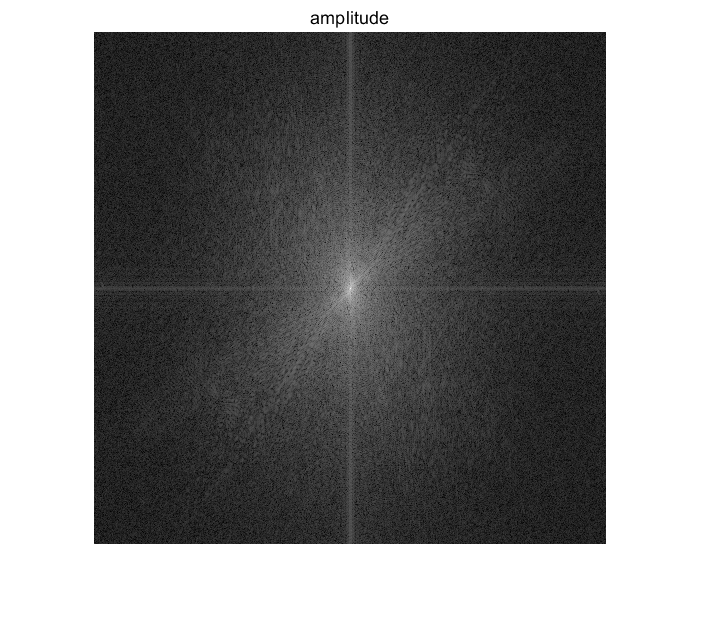

clear
img = imread("lenaG.bmp");

img = imrotate(img,90);

img = im2double(img);
img_fft = fft2(img);

img_fft = fftshift(img_fft);
imshow(log(abs(img_fft)+1),[]) 
title('amplitude')

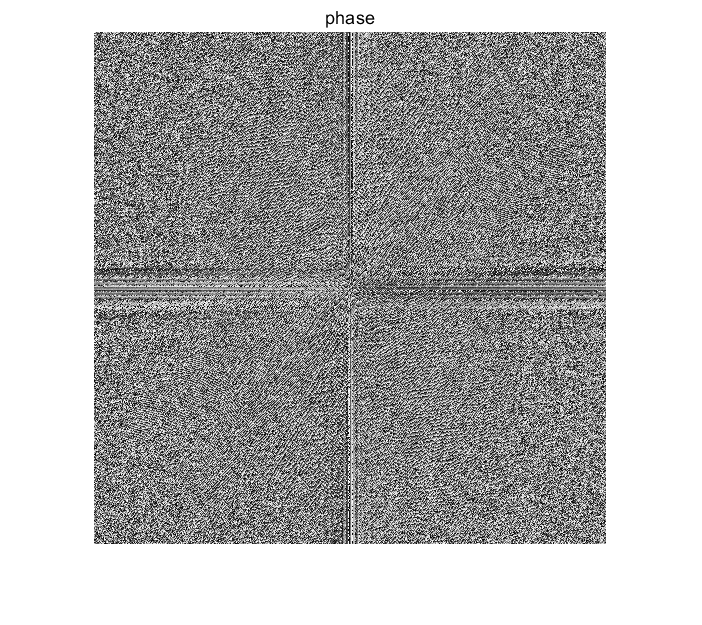

imshow(angle(img_fft)*180/pi,[])
title('phase')